# **MPEG Audio Project - Part B**

## **Reading an Audio signal:**

- Using Matlab built-in function audioread to read both the audio signal and the sampling frequency fs.

- Using audioinfo() function to extract the number of bits per sample, BPS. 

clear all
clc

filename = 'listen-to-the-ancient-egyptions-tv.wav'; 
[signal,fs] = audioread(filename);
% Bit per sample 
info=audioinfo(filename);
BPS_signal = info.BitsPerSample

BPS_signal = 16

sound(signal,fs);

## **Plot Spectral view of input audio signal:**

- Taking the DFT (FFT) of the signal to get and plot its frequency spectrum.

- Overlap and add method is used to implement FFT.

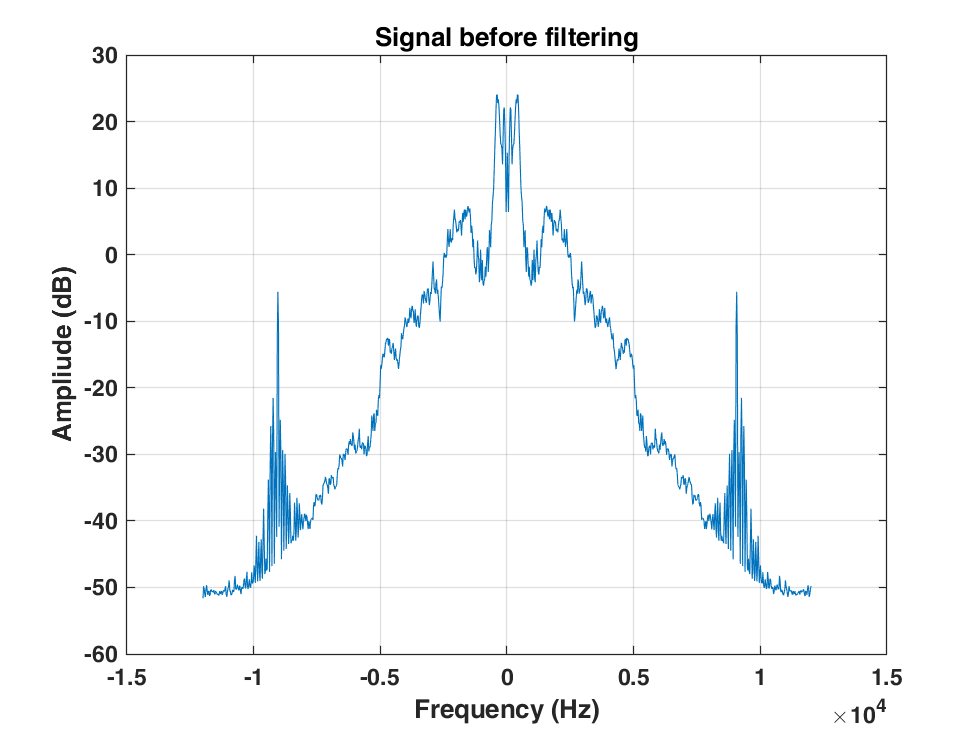

figure()
N = 1024;
hannwindow = hanning(N)'; %Hanning Window
signal2 =signal';
abs_sig = zeros(1,N);
phase_sig = zeros(1,N);
ns = 0;
for i = 0:N-(N/16)-1:length(signal2)
    if(i+N<length(signal2))
        %1024 point fft
        temp = signal2(i+1:i+N).*hannwindow;
        fsig = fftshift(fft(temp));
        abs_sig = abs_sig + abs(fsig);
        phase_sig = phase_sig + imag(fsig);
        
    else
        %Zero Padding
        extended = i+N-length(signal2);
        signal2 = [signal2, zeros(1,extended)];
        temp = signal2(i+1:i+N).*hannwindow;
        fsig = fftshift(fft(temp));
        abs_sig = abs_sig + abs(fsig);
        phase_sig = phase_sig + imag(fsig);
         
    end
    ns = ns +1;
end
%Plotting the signal before filtering
Signal_Spectrum = abs_sig / ns;
freq = linspace(-fs/2,fs/2,length(Signal_Spectrum));
plot(freq, 20*log10(Signal_Spectrum));
title('Signal before filtering');
xlabel('Frequency (Hz)');
ylabel('Ampliude (dB)');
grid on;

## **Filter Banks:**

- The filters are used for Time-to-frequency mapping of the signal.

- This filter divides the frequency spectrum into **32** equally spaced frequency sub-bands.

- The basic idea is to take a narrow low-pass filter (Prototype filter) and modulate copies of it to span the frequency domain.

- The PQMF filter bank consists of **32 **channels, each of which is a low-pass **filter h[n] **modulated by a** cosine** according to the following equation:

**hk[n] = h[n]*cos((k + 0.5)(n - 16)*pi/32)**

- Coefficients of the prototype filter h[n] are given in the book. 

- The 32 channels, therefore, lay down 64 copies of H(f) to divide up the frequency spectrum between **-Fs/2 **and** Fs/2**.

## **Downsampling:**

- To maintain the same date rate, we downsample the output of each filter by a factor of 32.

- We use MATLAB downsample() function to downsample the output of filter banks by integer factor 32. 

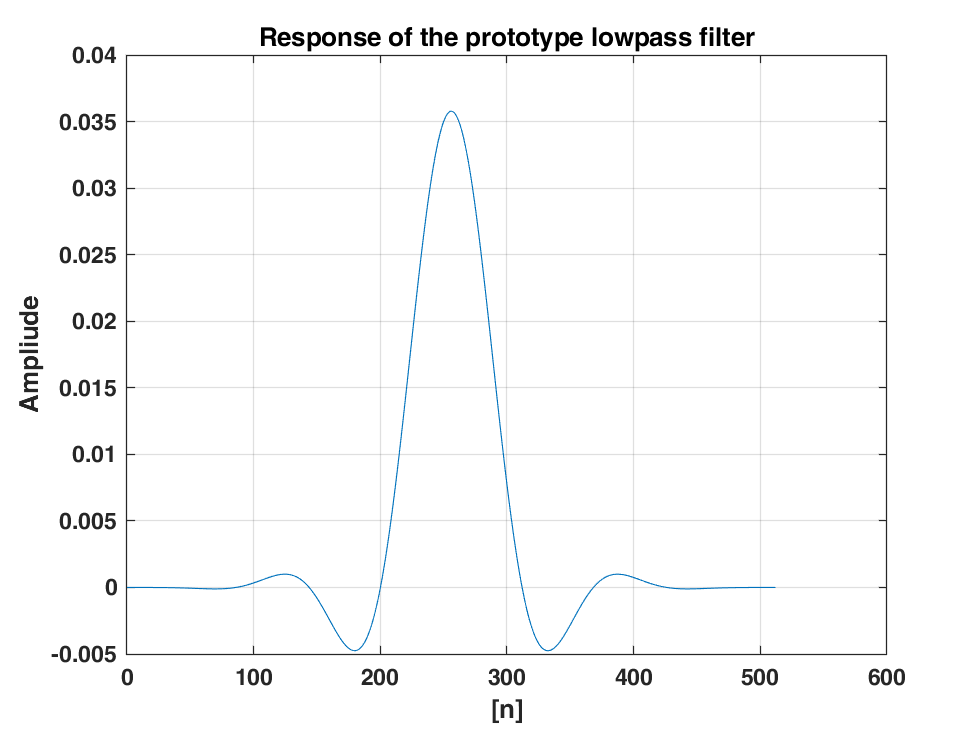

K = 32;
N = 512;
h = zeros(K,N);
% Define the prototype low pass filter response 
hp = PQMF(); % h[n]----> coefficients given in the book  

% Plot the Response of the prototype lowpass filter (PQMF Coeff)
n = 0:1:512;
figure();
plot(n, hp); grid on; title('Response of the prototype lowpass filter');
xlabel('[n]'); ylabel('Ampliude');



% Compute the response of the 32 filters
% hk[n] = h[n]*cos((k + 0.5)(n - 16)*pi/32)
for k = 0:1:31
    for n = 0:1:511
        h(k + 1,n + 1) = hp(n + 1)*cos((k + 0.5)*(n - 16)*pi/32);
    end
end
filteredSignals = [];

for k = 0:1:31
    seg = filter(h(k + 1,:),1,signal);
    segDown = downsample(seg,32);
    filteredSignals = [filteredSignals segDown];
end


## **Plot Spectral view of After Filterbank:**

figure()


## **Psychoacoustic model In theory:**

- A **psychoacoustic model **is applied to **the input signal **where the psychoacousticanalysis stage is performed with a 1024-point FFT to determine which frequency bands should be retained.

- **Threshold in quiet**, represents the lowest sound level that can be heard at a given frequency. Frequency components in a signal that fall below this level are irrelevant to our perception of sound and therefore they do not need to be transmitted. We applied this theory to frequency domain of the signal to remove inaudible components.

- **Auditory masking **occurs when the perception of one [sound](https://en.wikipedia.org/wiki/Sound) is affected by the presence of another sound. It occurs whenever the presence of a strong audio signal makes **a spectral neighborhood **of weaker audio signals imperceptible. 

## **Psychoacoustic model Implementation:**

- Take a 1024 point FFT of the input audio signal as done before in **Plot Spectral view of input audio signal section.**

- We computed the SPL corresponding to the coeffiecient of each frequncy sample in the spectrum of the signal.

- we deal with only the right side of the frequency domain representation from 0 to fs/2 since it is identical to the left side. (This would let us deal with 512 point instead of 1024 which will decrease computations required.)

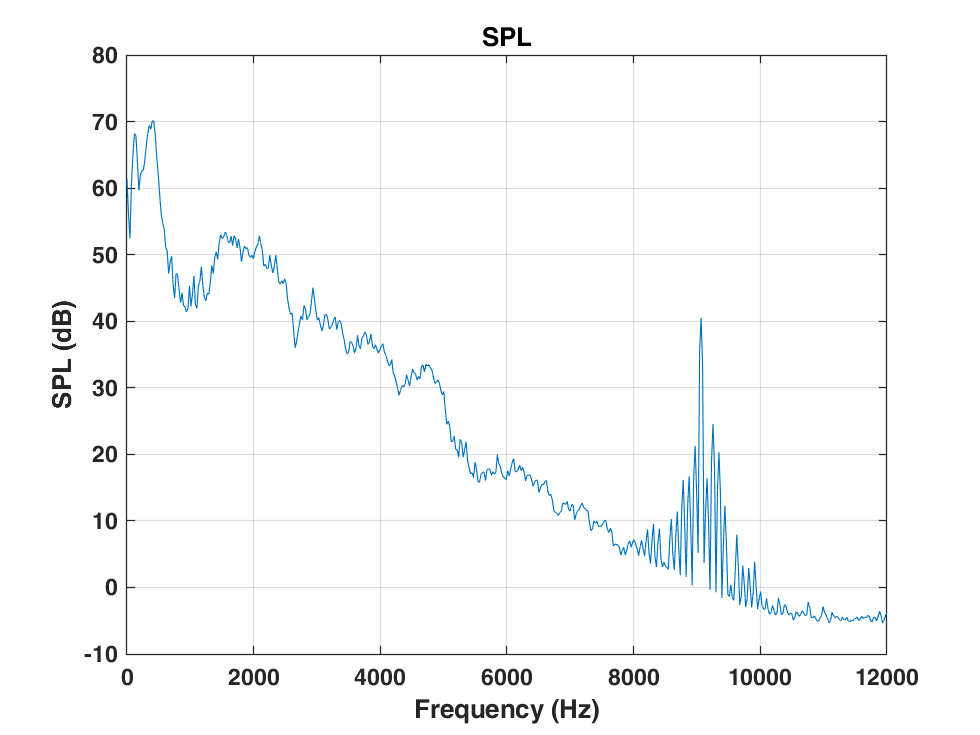

% layer II 
N = 1024; 
% Signal_Spectrum holds the frequency domain of the signal and has been
% computing above 

x = Signal_Spectrum; 
% vector to hold SPL values computed for each frequency sample(point).

Lk = zeros(1,N/2); 

for k = 0 : 1 : (N/2-1)
    Lk(k + 1) = 96 + 10*log10(4/N^2*(abs(x(k + 1 + N/2 ))^2)*8/3);
end

half_freq = linspace(0,fs/2,N/2);
figure(3)
plot(half_freq , Lk);
title("SPL"); grid on; xlabel('Frequency (Hz)'); ylabel('SPL (dB)')

## **Threshold of Quiet:**

- Function threshold_quiet computes corresponding threshold for the given frequency, then we compare to the SPL value for that frequency (This was computed in the previous section) 

- Equation used in the function threshold_quiet:

** A =  3.64*(f/1000).^(-0.8) - 6.5*exp(-0.6*((f/1000)-3.3).^2)+10^(-3)*(f/1000).^4**


for d = 1:1:length(Lk)
    f = half_freq(d);
    q_thresh = threshold_quiet(f);
    if Lk(d) < q_thresh
        Lk(d) = 0;
    end
end

## **Limiting Frequency Range:**

% Audible range 20 - 20 KHz
% spl ---> -10 db - 120 db 

## **Frequncy subbnds Extraction:**

% Divide Frequncy domain representation of the signal into 32 subbands 
subbands = [];
step = length(Lk)/32;

for i = 1:step:length(Lk)
    sub = Lk(i:i + step - 1);
    subbands = [subbands; sub];
    
end


## **Computing and applying the Tonal Maskers:**

- We find the tonal maskers for each subband by locationg indices of the local maximas of each subband.

- Then we approximate the masking threshold of the tonal masker by determining the range of frequencies that could be affected by the masker using **masking_threshold **function . Then we used the frequency of the masker f1 and its SPL value L1 and the value of the rightmost frequency that would be affected by the masker f2 and its SPL threshold of quie value L2 to constructe a straight line (that straight line would represent the masking threshold for the frequencies around the masker). This is done using the **threshold_2 function**.

-  Threshold_2 function determine the SPL value for the input frequency(freq_sub(j)), by using the straight line given by the interpolation between the f_1, spl_1, and f_2, spl_2. 

- We applied the maskers of each subband on the spectrum output of the threshold of quiet section (**Lk vector**) by looping over it and comparing the SPL at the given frequency with the output of function:

**threshold_2(f_1,f_2,spl_1,spl_2,freq_sub(j))**

- This process would produce the importnat frequencies in the spectrum of the signal (as the SPL of all the masked frequencies would be set to zero).

- The maskers would be applied only if their SPL value is greater than 0 dB.

% vectors to hold the value and the location of each tonal masker 
psk = [];
loc = [];
% loop over 32 subbands 
for q = 1:1:32
    % index used to determine the range of frequencies 
    % for the corresponding subband
    index = (q-1) *step + 1;  
    freq_sub = half_freq(index : index + step - 1);
    
    % determine the tonal maskers of the subband 
    [sub_max,I] = max(subbands(q , :));
    [psk,loc] = findpeaks(subbands(q , :),freq_sub);
    psk = [psk, sub_max];
    loc = [loc,freq_sub(I)];
    
    % For each given masker, loop over all the frequency points of
    % the given subband and apply the masking.
    for k = 1:1:length(psk)
        spl_1 = psk(k);
        f_1 = loc(k);
        % only apply the masker when its spl is greater than 0 dB
        if spl_1 > 0 
        %f_2 is the rightmost frequency that would be affected by the masker
            f_2 = masking_threshold(spl_1,f_1);
            % spl_2 is the minimum audible value of SPL for f_2
            spl_2 = threshold_quiet(f_2);
            for j = 1:1:length(freq_sub)
          
                if freq_sub(j) < f_2 && freq_sub(j)>f_1
                    y = 1.5 * threshold_2(f_1,f_2,spl_1,spl_2,freq_sub(j));
                    if Lk(j+step*(q-1))< y
                        Lk(j+step*(q-1)) = 0;
                    end
                end
            end
        end
    end
end


## **Maskers Output:**

- It shows the important frequencies contained in the spectrum of the input audio signal.

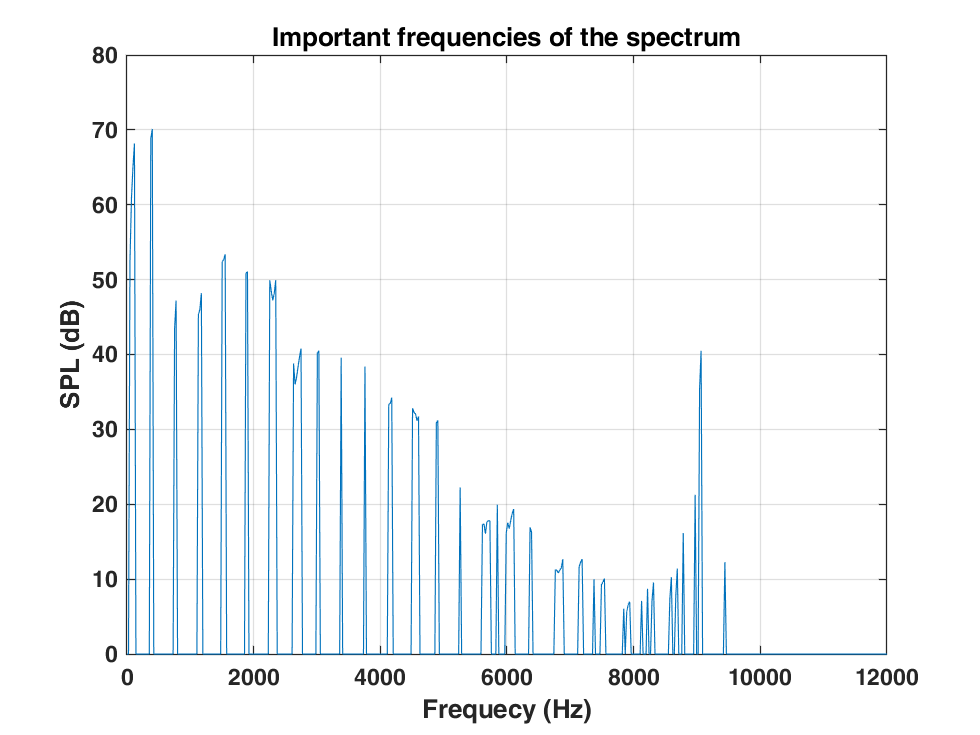

figure()
plot(half_freq,Lk)
title('Important frequencies of the spectrum'); grid on; 
xlabel('Frequecy (Hz)'); ylabel('SPL (dB)')

## **Taking fft of the output of the Filter Banks:**

- We take fft() for each subband (the 32 output subbands of the Filter Banks) and then compute the corresponding SPL values for each subband.

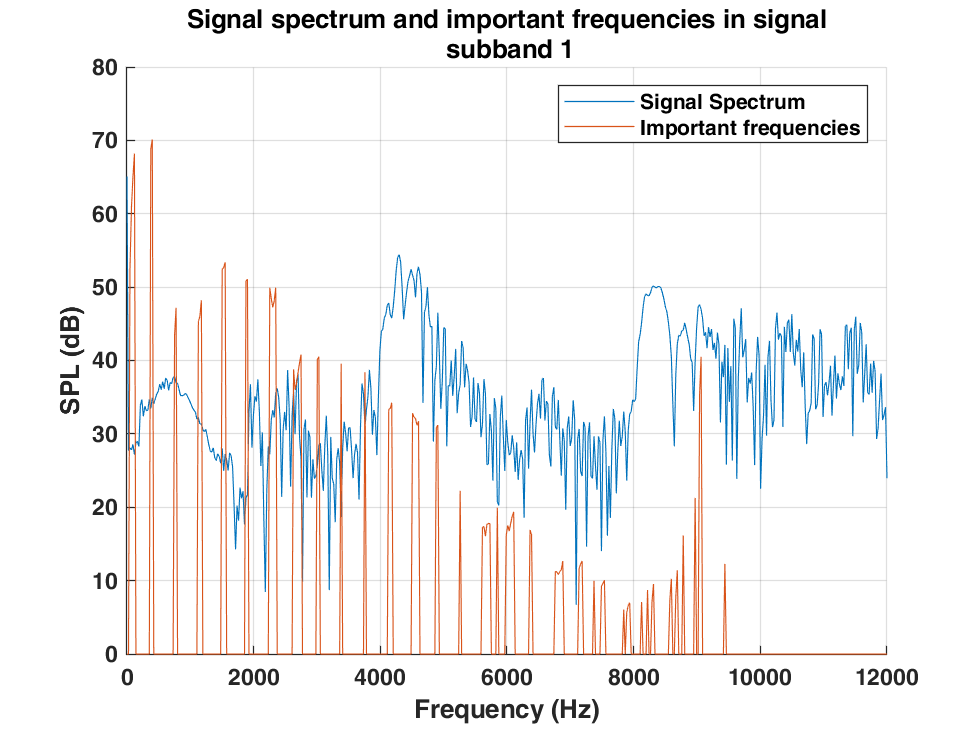

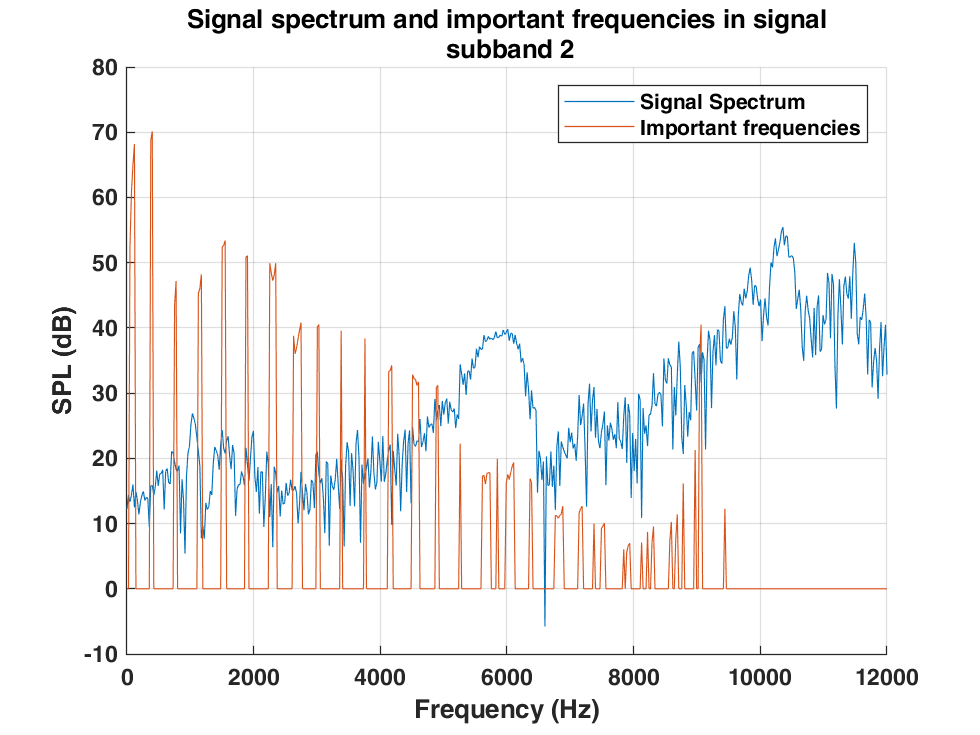

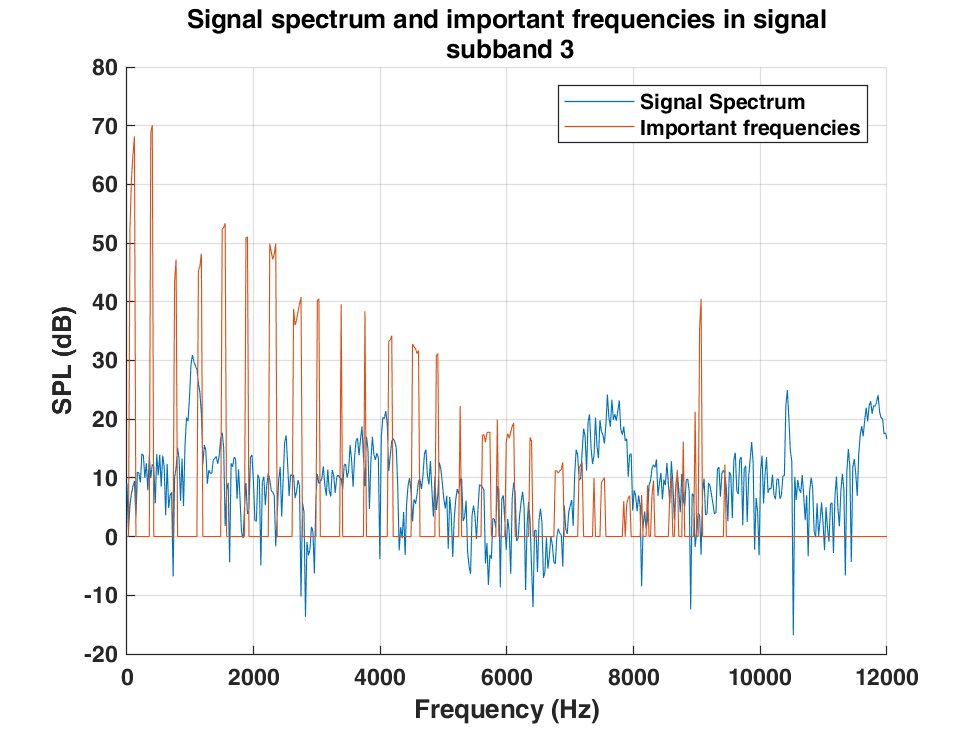

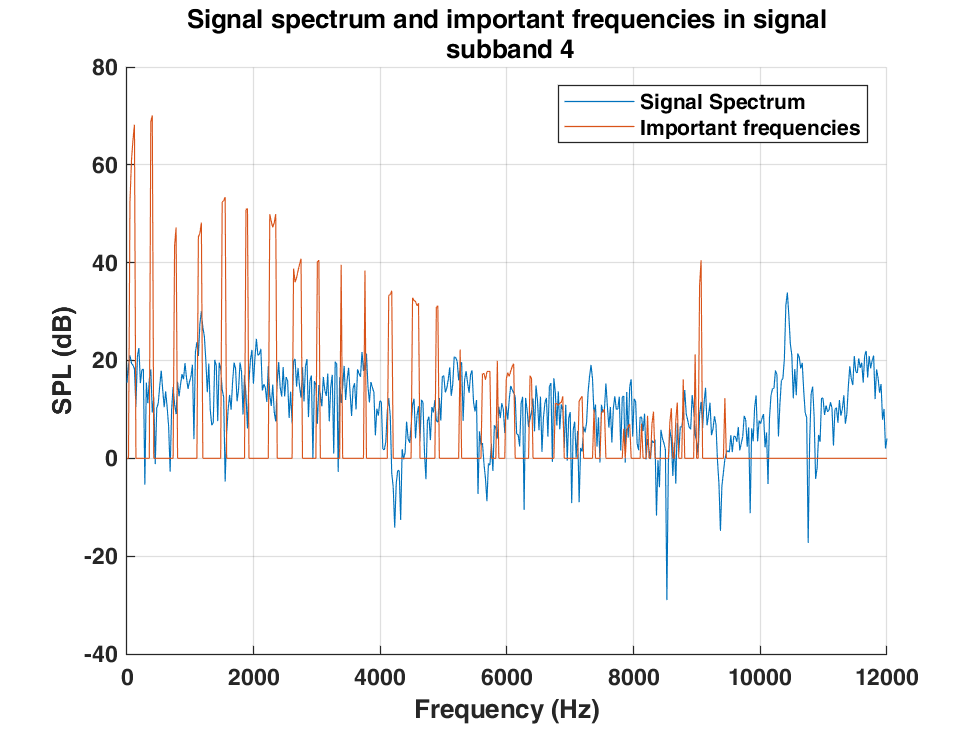

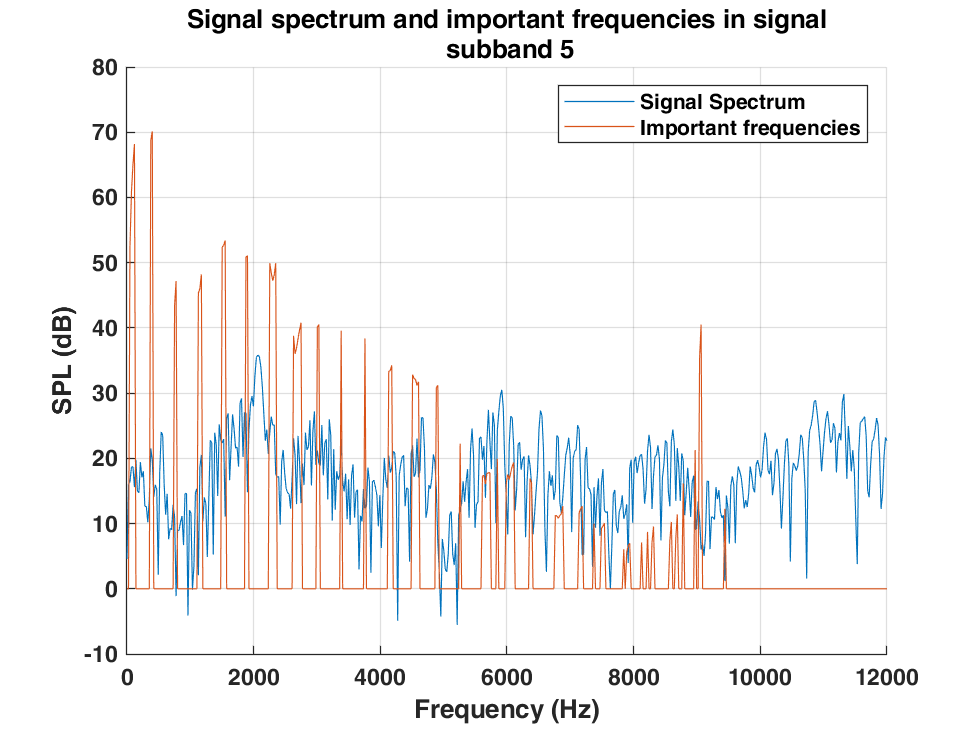

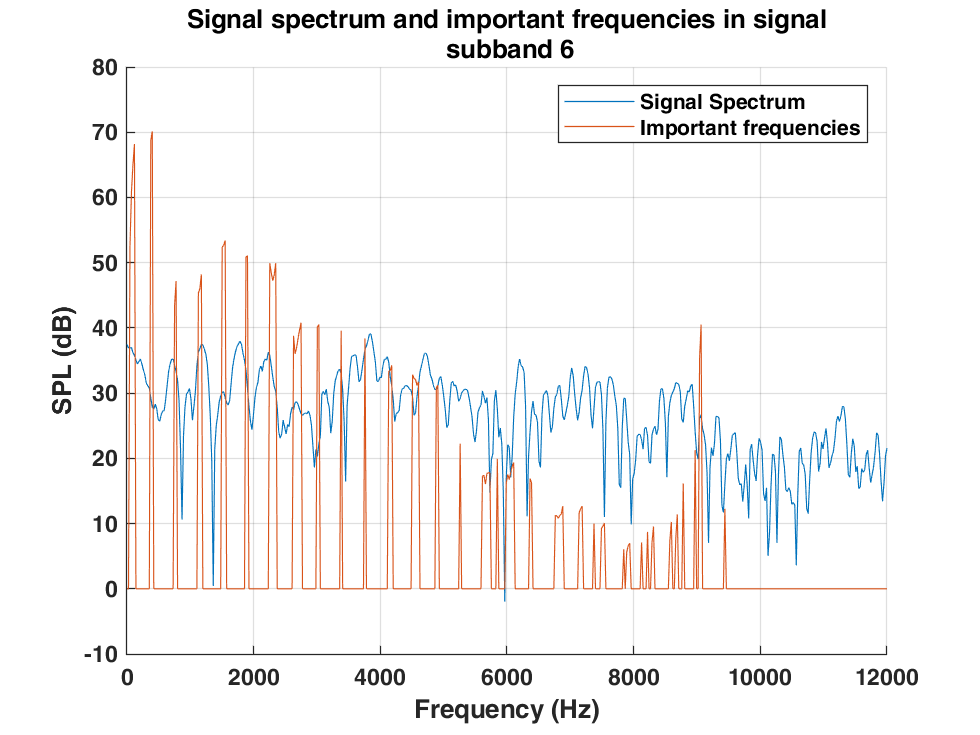

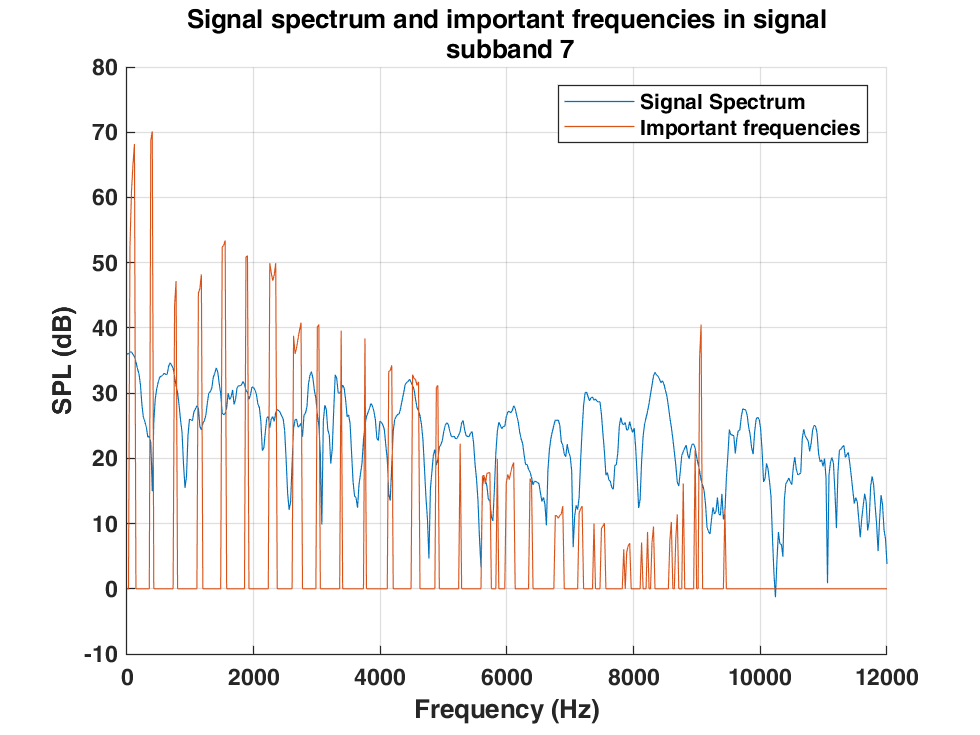

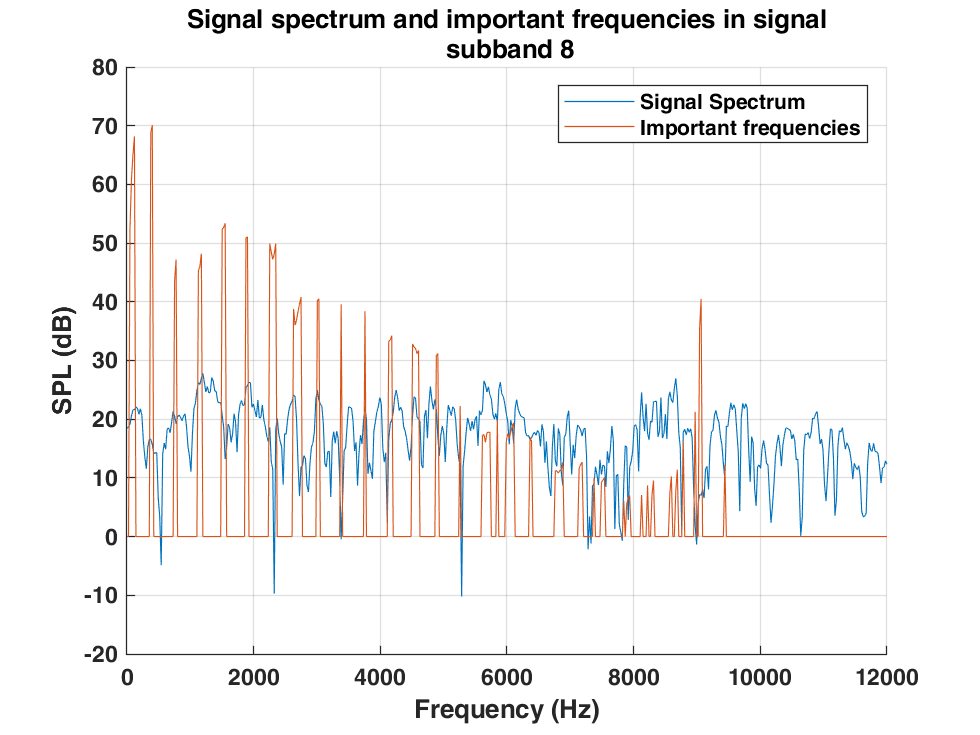

% Taking fft of each signal subband
subbands_freq = [];

for k = 1:1:32
    % 1024 fft 
    s_freq = fftshift(fft(filteredSignals(:,k),1024));
    % value in SPL
    s_freq = 96 + 10 * log10(4/N^2*(abs(s_freq).^2)*8/3);  
    s_freq = s_freq(513:1024);
    figure ()
    hold on 
    plot(half_freq,s_freq)
    plot(half_freq,Lk)
    title({'Signal spectrum and important frequencies in signal';[' subband ',num2str(k)]});
    grid on; xlabel('Frequency (Hz)'); ylabel('SPL (dB)');
    legend('Signal Spectrum', 'Important frequencies');
    
    subbands_freq = [subbands_freq s_freq];
end

## **Multiplying SPL values:**

- Multiply the SPL values of each subband  with the vecrtor holding the importnat frequecies in the spectrum of the input signal.

- This would determine the number of important frequencies contatined in each subband.

- Then the resulted SPL values are summed to produce one number representing each subband. **sum_spl** vector holds this summation.

subband_masked = [];
sum_spl = [];

for i = 1:1:32
    sub_masked = subbands_freq(:,i).*transpose(Lk/max(Lk));
    subband_masked = [subband_masked sub_masked];
    s = sum(sub_masked);
    sum_spl = [sum_spl s];
end

## **Ranking the 32 Subband:**

- We sort the sum_spl vector in descending order.

- Then we assign higher number of bits for the highest subbands. Each 4 subbands are given the same number of bits. this number will decreases by a specific amount for the next 4 subbands.

subband_bits = zeros(1,32);
count = 0;
if BPS_signal<=16
    BPS = BPS_signal;
else
    BPS = 16;
end

b = BPS;

for i=1:1:32
    [smax,index] = max(sum_spl);
    index;
    
    if count < 4
        b = BPS;
    elseif count<8
        if BPS - 10 >= 2 
            b = BPS - 10;
        else
            b = 2;
        end
    elseif count<12
        if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
        end
    elseif count<16
        if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
        end
    elseif count<20
       if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
       end
    elseif count<24
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 2;
        end
    elseif count<28
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 1;
        end
    else
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 1;
        end
    end
    subband_bits(index) = b;
    count = count + 1;
    sum_spl(index) = -inf;
end

## **Quantization:**

- Data is divided into frames, each frame contains 384 samples, 12 samples from each of the 32 filtered sub-bands. 

- Quantization is carried out by dividing each sub-band into 12 samples and quantize them using a **uniform midtread quantizer** having a number of steps for that sub-band determined in the previous section.

- With R number of bits the midtread quantizer allows for **2^(R-1)** different codes.

- The **Implemented** Midtread Quantizer is based on the idea of **Uniform Spacing between Levels**. 

- The basic Uniform Midtread Quantizer which depends on the symmetry between how positive and negative signals are quantized, necessarily have an **odd** number of output steps that are equally divided into postive and negative levels.

- Dividing the steps into not equal number of positive and negative steps, but depending on the maximum and minimum values of samples reduces the quantization error. 

Encoded_signal = []; % Vector to hold the Encoded Signal
levels_quan = [];    % Vector to hold the Quantization Levels' Values 

% Dimensions (rows, columns) of the filtered signal after taking fft
[R,L] = size(filteredSignals); 

% Midtread Quantization of samples in each subband 
for index = 1:12:R % index to indicate the start of each subband.
    
    index2 = index + 12 -1; % index to indicate the end of each subband.
    
    for i = 1:1:32 % index for subband number
         b = subband_bits(i); % number of bits for each sub 

        if index2 < R
            % Calling Quantization Function to quantize the 12-samples of each subband
            [maxi,mini,sampled_quan] = Quan(filteredSignals(index : index2 , i),b);
            levels_quan = [levels_quan sampled_quan]; % Storing decimal values of the samples' level numbers in a row vector
        else
            % Case of having the last subband with samples less than 12
            break;            
        end
        % Forming and reshaping the Encoded Signal to be stored in a row vector. 
        sampquan = de2bi(transpose(sampled_quan),b); % Converting the quantized samples from Quantization Function into Binary values
        sampquan = sampquan'; % Taking the transpose of the binary values vector
        sampquan = reshape(sampquan,1,[]); % Reshaping the values to store them in a row vector
        
        % Encoded Signal holds Quantized Samples, Max and Min Values in each 
        % subband, number of bits used in Quantization to use tham in Dequantization 
        Encoded_signal = [Encoded_signal b maxi mini sampquan];
    end
    
end

## **Decoder:**

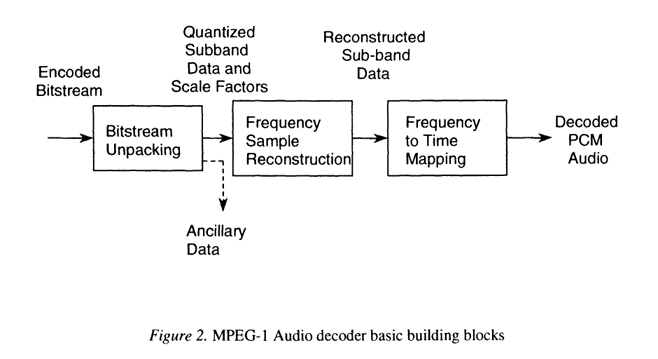

- Decoder aims to reconstruct the encoded signal by restoring the values of the samples before they were quantized.

- A Uniform Midtread Dequantizer having a number of steps as the Quantizer, so that quantization and dequantization are done using the same number of levels for each subband.

- To perform Frequency to Time Mapping, the dequantized samples are passed through synthesis filters which are defined in terms of the analyzing filters to avoid aliasing of the signal.

### **Synthesis filter:**

### **Dequantization:**

- The decoder restores the quantized spectral components of the signal by decoding the spectral components of each subband as follows:

- Number of bits used in quantizing the subband is obtained from the encoded signal.

- Maximum value used in quantizing the subband is obtained from the encoded signal.

- Minimum value used in quantizing the subband is obtained from the encoded signal.

- Quantized Levels of the subband is obtained from the encoded signal.

- DeQuan() function is used to dequantize the subband and obtain its spectral components.

- The previous steps are applied for each subband, then the spectral components of the signal is reconstructed. 

index = 1;
decoded_subbands = []; % Vector to hold the Decoded Subbands
decoded_samples = []; % Vector to hold the Decoded Samples
counter = 1;  
levels_dequan = []; % Vector to hold the Dequantization Levels' Values 

% Midtread Dequantization of samples in each subband 
while(index < length(Encoded_signal))  % Index of 

% Encoded Signal is formed such that it holds the following parameters for each Subband:
% 1)No. of bits, 2)Maximum Sample Value, 3)Minimum Sample Value 4)Quantized Samples

b = Encoded_signal(index); % No. of bits used in Quantization
maxi = Encoded_signal(index + 1); % Maximum Sample Value in the subband
mini = Encoded_signal(index + 2); % Minimum Sample Value in the subband

index_start = index + 3;  % index to indicate the start of each subband.
index_end = index_start + 12 * b - 1; % index to indicate the start of each subband.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
seg_1 = Encoded_signal(1 , index_start : index_end);  % Vector to hold the samples of each subband
seg_2 = reshape(seg_1,[], 12); % Reshaping to be used by bi2de() function
seg_3 = seg_2'; % Transpose to be used by bi2de() function
seg_4 = bi2de(seg_3); % Convert the binary values of the levels' numbers into decimal numbers
seg_5 = seg_4 + 1; 
seg = DeQuan(maxi, mini, b , seg_5); % Dequantize to obtain the value that corresponds to the level number
%levels_dequan = [levels_dequan seg_4']; % ********Forming the dequantized levels for each subband 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
decoded_samples = [decoded_samples; seg]; % Forming the dequantized levels for each subband 

% Constructing the Matrix of the 32 subands
  if counter == 32
     decoded_subbands = [decoded_subbands decoded_samples];
     decoded_samples = [];
     counter = 1;
  else
     counter = counter + 1;
  end
index = 1 + index_end; 
end 

decoded_subbands = decoded_subbands';

## **Synthesis filters:**

- We need to reconstruct the time-domain representation of the audio signal from its frequency representation.

- The data is up-sampled by a factor of 32 prior to recombining the sub-band signals to space it out back to the original data rate.

- To set up the filter banks so that there is no aliasing of the signal, the synthesis filters are defined in terms of the analyzing filters as the following.

**gk[n] = hk[N-1-n]**

**gk[n] = 32 *h[n] * cos((k + 0.5)*(n + 16)*pi/32)**

recievedSignals = decoded_subbands; 
g = zeros(K,N);

for k = 0:1:31
    for n = 0:1:511
        g(k + 1,n + 1) = 32 * hp(n + 1)*cos((k + 0.5)*(n + 16)*pi/32);
    end
end

reconSignal = 0;
for k = 0:1:31
    % Upsampling the subbands before using the synthesis filter  
    seg = upsample(recievedSignals(:, k+1) , 32) ;
    % Filtering the signals 
    segFiltered = filter(g(k + 1,:),1,seg);
    % summing the output of the synthesis filters to produce the
    % reconstructed signal
    reconSignal = reconSignal + segFiltered;
end

## **Compression Ratio:**

- Compression Ratio is the ratio of uncompressed data size to the compressed data size 

Compression_Ratio = compression(subband_bits, BPS_signal, length(signal))

Compression_Ratio = 4.1290

## **Plot Spectral view of the reconstructed audio signal :**

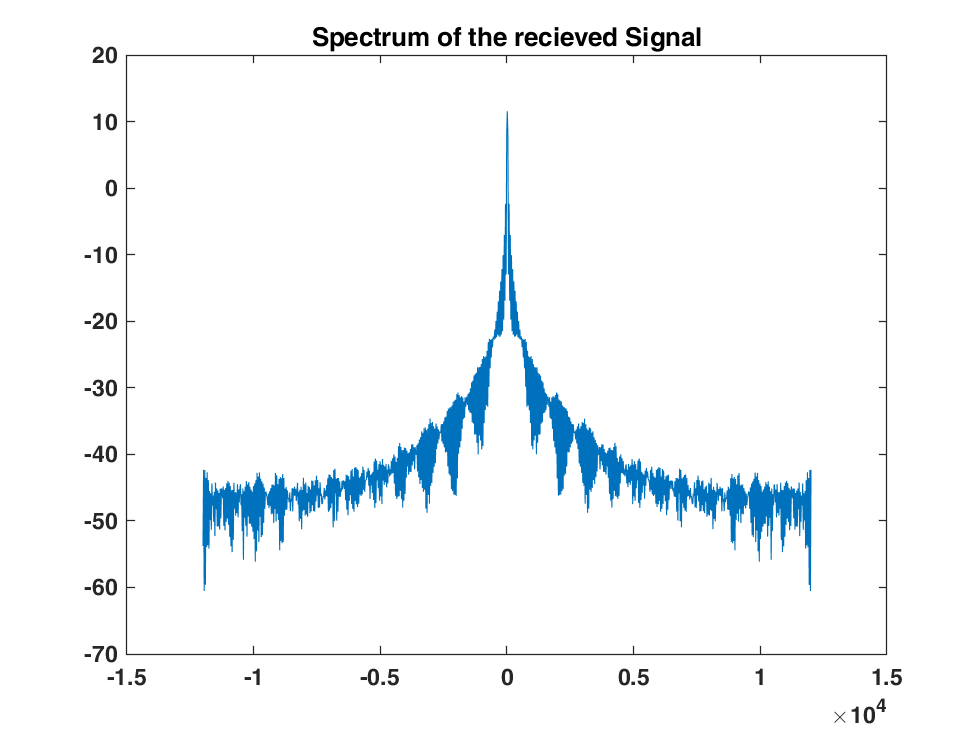

figure()
Signal_Spectrum_recieved = fftshift(fft(reconSignal , 1024));
freq = linspace(-fs/2,fs/2,length(Signal_Spectrum_recieved));
plot(freq, 20*log10(abs(Signal_Spectrum_recieved)));
title('Spectrum of the recieved Signal')

## **Subjective evaluation Test: **

- For the Subjective evaluation, each team member has listened carefully to both the original and compressed audio signals and decide his/her Mean Opinion Score based on the following criteria 

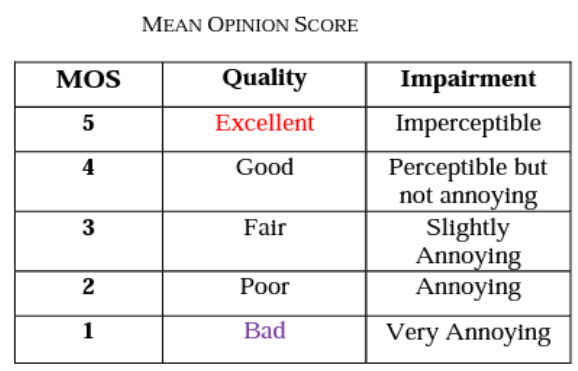

- The **following table** shows the scores for each team member:

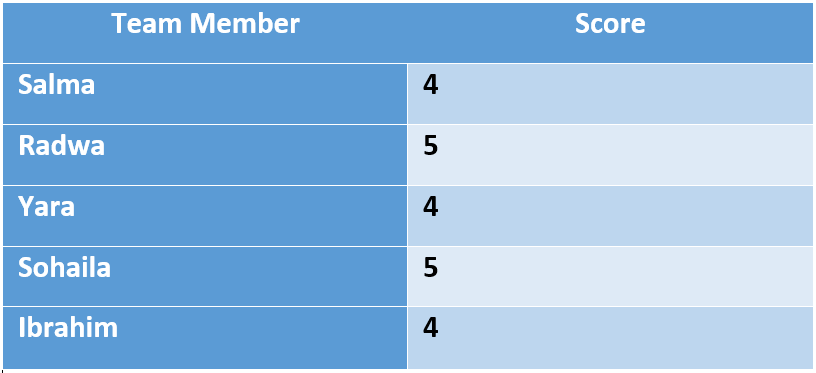

sound(reconSignal, fs)

## ODG:

- The objective difference grade (ODG) is calculated by perceptual evaluation of the audio quality algorithm specified in ITU BS.1387-1.

- It corresponds to the subjective difference grade used in human-based audio tests. 

- The ODG ranges from 0 to −4 and is defined as follows:

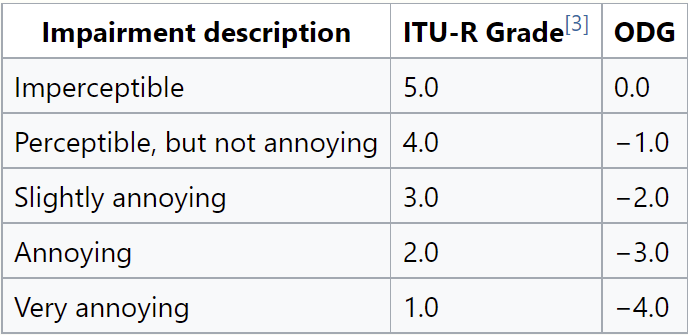

- To find ODG, we used the implmented model from: 

[NikolajAndersson/PEAQ: This repo contains a Matlab version of the Perceptual Evaluation of Audio Quality algorithm (github.com)](https://github.com/NikolajAndersson/PEAQ)

% Resampling the audio signals since ODG function deals with fs = 48 kHz only. 
[P,Q] = rat(48e3/fs);
abs(P/Q*fs-48000);
uncompressed_audio = resample(signal,P,Q);
compressed_audio = resample(reconSignal,P,Q);
audiowrite('Functions\ODG\uncompressed.wav',uncompressed_audio, 48e3);

audiowrite('Functions\ODG\compressed.wav',compressed_audio, 48e3);


ref = 'Functions\ODG\uncompressed.wav';
test = 'Functions\ODG\compressed.wav';

[ODG, ] = PQevalAudio_fn(ref, test)

 WAVE file: Functions\ODG\uncompressed.wav
   Number of samples : 480000 (10 s)
   Sampling frequency: 48000
   Number of channels: 1 (16-bit integer)
 WAVE file: Functions\ODG\compressed.wav
   Number of samples : 479232 (9.984 s)
   Sampling frequency: 48000
   Number of channels: 1 (16-bit integer)
>>> Number of samples differ
>>> Number of samples differ: using the minimum
PEAQ Data Boundaries: 18 (0.000 s) - 479999 (10.000 s)


ODG = -1.3994